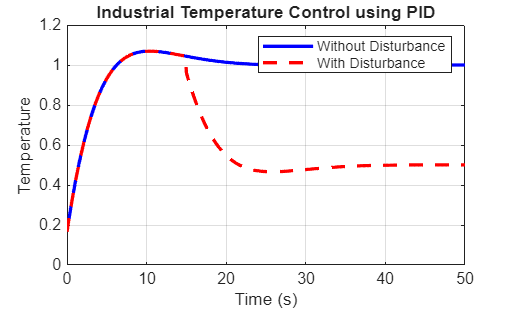

clc;
clear;
close all;

% Plant: G(s) = 2/(10s+1)
G = tf(2, [10 1]);

% PID Controller
Kp = 2;
Ki = 0.4;
Kd = 1;
C = pid(Kp, Ki, Kd);

% Closed-loop system
T = feedback(C*G, 1);

% Time vector
t = 0:0.1:50;

% Step response (no disturbance)
[y, t] = step(T, t);

% Disturbance (heat loss at t = 15 sec)
d = zeros(size(t));
d(t >= 15) = -0.5;

% Response with disturbance
y_dist = lsim(T, d, t);

% Final output
y_total = y + y_dist;

% Plot
figure;
plot(t, y, 'b', 'LineWidth', 2); hold on;
plot(t, y_total, 'r--', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Temperature');
legend('Without Disturbance', 'With Disturbance');
title('Industrial Temperature Control using PID');
grid on;